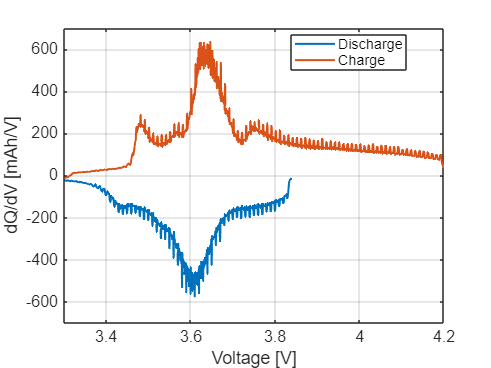

clear; clc; close all;

filename = 'C-14.xlsx';

data = readtable(filename, 'VariableNamingRule','preserve');

% Kolumner från din Excel-fil
I = data{:,6};   % Current(mA)
V = data{:,7};   % Voltage(V)
Q = data{:,8};   % Capacity(mAh)

V = double(V);
I = double(I);
Q = double(Q);

valid = ~isnan(V) & ~isnan(I) & ~isnan(Q);
V = V(valid);
I = I(valid);
Q = Q(valid);

% Ta bort vila/rest
active = abs(I) > 0.01*max(abs(I));

edges = diff([false; active; false]);
startIdx = find(edges == 1);
endIdx   = find(edges == -1) - 1;

segments = struct([]);

for k = 1:length(startIdx)
    idx = startIdx(k):endIdx(k);

    if length(idx) < 20
        continue
    end

    Imean = mean(I(idx));

    if Imean > 0
        type = "Charge";
    else
        type = "Discharge";
    end

    segments(end+1).idx = idx; %#ok<SAGROW>
    segments(end).type = type;
end

% Första cykeln = första två aktiva segmenten
firstCycle = segments(1:min(2,length(segments)));

figure;
hold on;

for k = 1:length(firstCycle)

    idx = firstCycle(k).idx;

    Vseg = V(idx);
    Qseg = Q(idx);

    [Vdqdv, dQdV] = make_dqdv(Vseg,Qseg);

    % Visa bara relevant voltage-område
    mask = Vdqdv >= 3.3 & Vdqdv <= 4.2;
    Vdqdv = Vdqdv(mask);
    dQdV  = dQdV(mask);

    plot(Vdqdv,dQdV,'LineWidth',1.5,'DisplayName',firstCycle(k).type);
end

xlabel('Voltage [V]');
ylabel('dQ/dV [mAh/V]');

legend('Location','best');
grid on;
box on;

xlim([3.3 4.2]);
ylim([-700 700]);

set(gca,'FontSize',12);


%% Funktion för dQ/dV
function [Vout,dQdVout] = make_dqdv(V,Q)

    V = V(:);
    Q = Q(:);

    ok = ~isnan(V) & ~isnan(Q);
    V = V(ok);
    Q = Q(ok);

    % Sortera
    [V,idx] = sort(V);
    Q = Q(idx);

    % Ta bort dubletter
    [V,uniqueIdx] = unique(V);
    Q = Q(uniqueIdx);

    % LÄTT smoothing (inte för mycket!)
    Qsmooth = smoothdata(Q,'movmean',10);

    % Derivata
    dQdV = gradient(Qsmooth) ./ gradient(V);

    % Liten smoothing på derivatan
    dQdV = smoothdata(dQdV,'movmean',5);

    % Ta bort extrema spikes (men inte för aggressivt)
    limit = prctile(abs(dQdV),99.5);
    keep = abs(dQdV) < limit;

    Vout = V(keep);
    dQdVout = dQdV(keep);

end